# Unidad 6 - TP08b

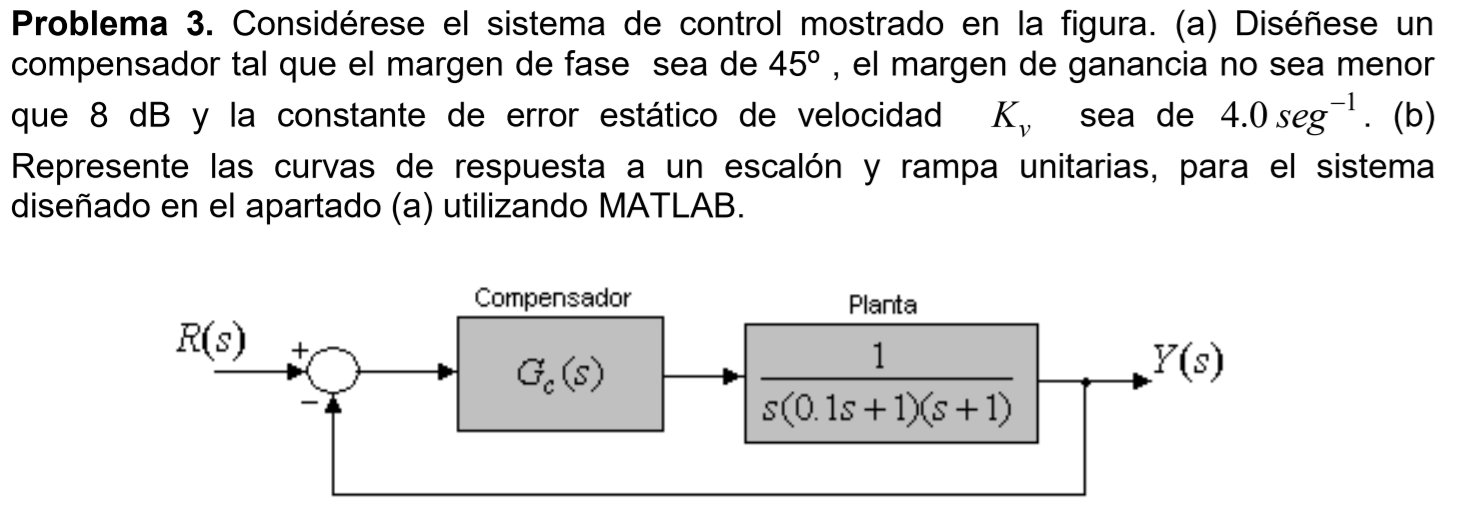

## Requisitos

- MF = 45°

- MG > 8dB

- 
$$K_V =4\;s^{-1}$$


## Analizamos la planta

s = tf('s');
G = 1/(s*(s+1)*(s/10+1));
H = 1;
bode(G*H);
grid on;

Del análisis previo podemos observar que al no estar comprometidos con el margen de ganancia y faltarnos un poco del margen de fase podemos intentar una primera aproximación con una red de **adelanto de fase.**


$$G_C \left(s\right)=k_c \;\alpha \;\frac{\textrm{sT}+1}{\textrm{sT}\alpha +1};\;0<\alpha <1$$


## Diseño

Lo primero que buscamos diseñar es la condición de error en régimen permanente.

Por lo tanto y recordando que la constante del controlador la ponemos con la ganancia de la planta, queda entonces,

$k_V =\lim_{s\to 0} \;s\;\left(k_c \;\alpha \right)\frac{\textrm{sT}+1}{\textrm{sT}\alpha +1}\;\frac{1}{s\left(s+1\right)\left(\frac{s}{10}+1\right)}$; $k=k_C \;\alpha$


$$k_v =k$$



$$k=4\;s^{-1}$$


Con el valor de k observamos los márgenes de nuestro nuevo sistema,

k = 4;
margin(k*G*H);
grid on;

Necesitamos exactamente 27° para cumplir la condición del MF propuesta, le adicionamos entre 5° y 12° para compensar el corrimiento que sufrira por los proximos pasos de diseño.

phm = 27+10;
phm_rad = phm/180*pi;
alfa = (1-sin(phm_rad))/(1+sin(phm_rad))

Ahora obtenemos el valor de $k_c$

kc = k/alfa

Ahora buscamos la atenuación necesaria para obtener el MF calculado

Att = -20*log10(1/sqrt(alfa))

Nuevamente ingresamos con este valor de atenuación en el gráfico de bode para hallar la frecuencia a la cual se produce dicha atenuación,

bode(k*G*H);
grid on;

Observando entonces que la frecuencia $w_m =2\ldotp 69\;\frac{\textrm{rad}}{s}$. Finalmente obtenemos la ubicación del polo y cero de nuestor compensador.

wm = 2.69;
T = 1 / (sqrt(alfa)*wm)
z = wm * sqrt(alfa)
p = wm / sqrt(alfa)

Quedando finalmente nuestro compensador,


$$G_c \left(s\right)=16\;\frac{\left(s+1\ldotp 35\right)}{\left(s+5\ldotp 40\right)}$$


## Verificación

Gc = (kc*alfa) * (s*T+1)/(s*T*alfa+1);
M = feedback(G,H);
Mc = feedback(Gc*G, H)

% Bode del compensador
bode(Gc);
grid on;

% Margenes de fase y ganancia.
margin(Gc*G*H);
grid on;

% Comparativa de los bode.
bode(G*H, Gc*G*H);
grid on;
legend("Sin compensar", "Compensado");

% Respuesta al escalón
step(M, Mc);
grid on;
legend("Sin compensar", "Compensado");

% Respuesta a la rampa
[y,t]=step(M*tf(1,[1 0]), 10);
[yc,tc]=step(Mc*tf(1,[1 0]), 10);
plot(t,t,'k', t,y,'r', tc,yc,'b');
legend("Rampa unitaria", "Sin compensar", "Compensado");
grid on;